datapath = ...
    {"/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220518_AchsensorHEK002_laser/",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221024_AchsensorHEK002_laser",...
    "/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221024_AchsensorHEK003_laser/"...
    }

datapath = 1×3 cell array
    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20220518_AchsensorHEK002_laser/"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221024_AchsensorHEK002_laser"]}    {["/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221024_AchsensorHEK003_laser/"]}




StateYao_file = ...
    {"analysis_offset0/20220518_AchsensorHEK002_Analysis2022-09-12.mat",...
    "analysis_offset0/20221024_AchsensorHEK002_Analysis2022-10-25.mat",...
    "analysis_offset0/20221024_20221024_AchsensorHEK003_Analysis2022-10-25.mat"...
    }

StateYao_file = 1×3 cell array
    {["analysis_offset0/20220518_AchsensorHEK002_Analysis2022-09-12.mat"]}    {["analysis_offset0/20221024_AchsensorHEK002_Analysis2022-10-25.mat"]}    {["analysis_offset0/20221024_20221024_AchsensorHEK003_Analysis2022-10-25.mat"]}


all_epochs = [2 3 4]; % all the epochs
drug_epochs = [2 3 4];  % the drug epochs that we want to do the epoch based calculation (always add one bigger that the last epoch needed to be calculated)

CyclePositions = [1 2]

CyclePositions =      1     2


baseline_acq_num = 5; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 5; % epoch based response calculation

FigureVisible = 'off'

numCycle = 1

numCycle = 2

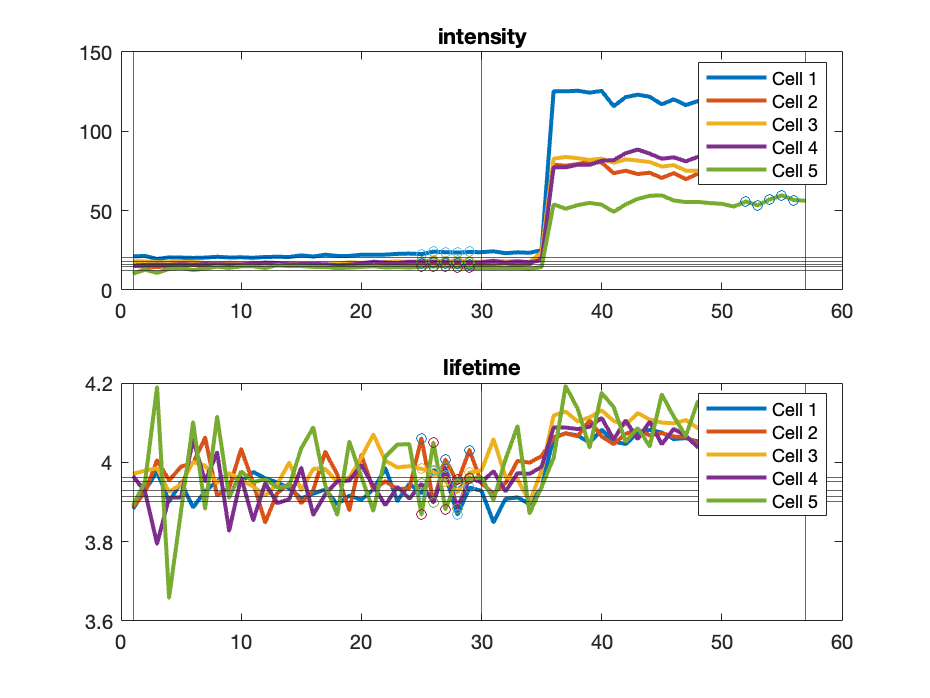

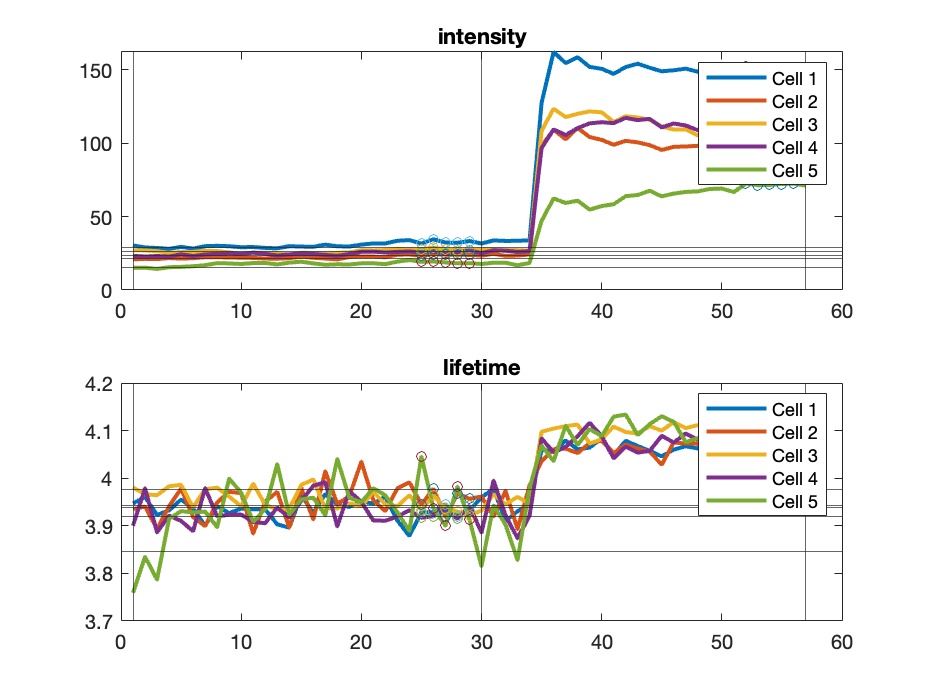

epoch_response_intensity_norm_all = 1×2 cell array
    {2×5 double}    {2×5 double}


epoch_response_lft_norm_all = 1×2 cell array
    {2×5 double}    {2×5 double}


epoch_response_intensity_all = 1×2 cell array
    {2×5 double}    {2×5 double}


epoch_response_lft_all = 1×2 cell array
    {2×5 double}    {2×5 double}


for i = 1:3
    cd(datapath{i})
    load(StateYao_file{i})

    Yao_GUI_ReviseROIsBasedOnCoordinates(CyclePositions)
    CalculateROIBasedOnTopPixels(5, 0.66, CyclePositions)
    [lft_all,intensity_all, EpochStartAcq_all, AcqTime_all] = FLIM_posthoc_dendriteMode_topPixels(CyclePositions);
    [epoch_response_intensity_norm_all,epoch_response_lft_norm_all,epoch_response_intensity_all,epoch_response_lft_all] = Epoch_based_calculation(all_epochs, drug_epochs, CyclePositions, baseline_acq_num, epoch_acq_num, EpochStartAcq_all, intensity_all, lft_all)

    save([stateYao.baseName,'topPixels_analysis.mat'],'epoch_response_intensity_norm_all','epoch_response_lft_norm_all','epoch_response_intensity_all','epoch_response_lft_all','lft_all','intensity_all', 'EpochStartAcq_all', 'AcqTime_all')
end

% acq = 40
chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;

figure
h=heatmap(spc.projects{1});
h.Colormap=gray
Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 600];

% acq = 70
chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;

figure
h=heatmap(spc.projects{1});
h.Colormap=gray
Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 600];

% acq = 114
chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;

figure
h=heatmap(spc.projects{1});
h.Colormap=gray
Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 600];

% acq = 158
chan=1;

figure
image(spc.rgbLifetimes{chan});
axis off;

figure
h=heatmap(spc.projects{1});
h.Colormap=gray
Ax=gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
h.ColorbarVisible='off';
h.GridVisible='off';
h.ColorLimits=[0 600];